%i = 11;
%j = 4;
p = 18;
q = -14;
r = 12;
s = 17;

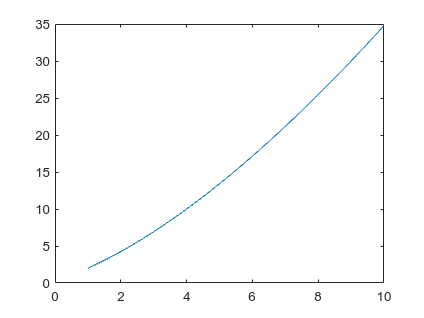

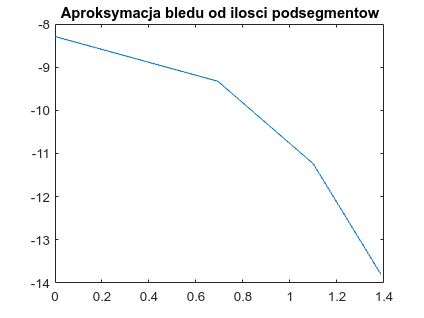

clf;
assigment1('sqrt(x).*x+sqrt(x)', 1, 10);

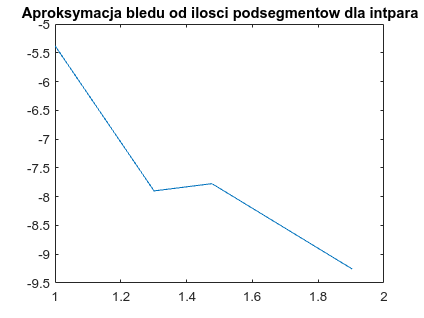

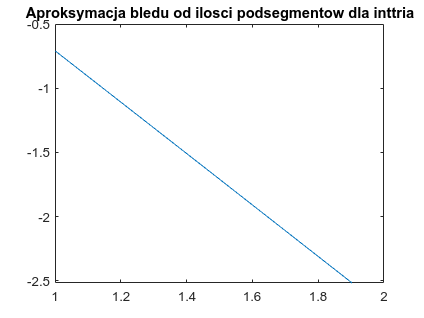

clf;
assigment3('sqrt(x).*x+sqrt(x)', 1, 10);

clf
assigment5(p, q, r, s);

Roznice miedzy wartosciami A*qi a lambda*qi:
   7.4940e-15

  -1.1102e-14

  -3.7748e-15

  -4.4409e-15

Wartosci iloczynow skalarnych wektorow wlasnych macierzy (gdy wynosza 0, sa one prostopadle):
  -1.1102e-16

   2.4980e-16

  -5.8981e-17

   2.7756e-17

  -1.3878e-16

   5.5511e-17

Wartosc sumy wartosci na przekatnej macierzy A oraz wartosci wlasnej tej macierzy:
    33

    33

Wartosc wyznacznika macierzy A orz iloczynu wartosci wlasnych macierzy:
  -4.3375e+04

  -4.3375e+04



clf;
assigment6(p, q, r, s);

Wartosc wektora wlasnego macierzy A, wyznaczonego metodą potęgową:
    0.3898
    0.1729
    0.5730
    0.6999

Wartosc wlasna macierzy A, wyznaczona metodą potęgową:
   26.7784

Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia -10:
   -0.0112
    0.9637
   -0.2664
   -0.0145

Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:
  -16.2751

Ilosc iteracji:
     6

Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia 5:
    0.0274
    0.1930
    0.7272
   -0.6582

Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:
    6.0523

Ilosc iteracji:
     5

Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia 15:
    0.9206
   -0.0673
   -0.2673
   -0.2766

Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:
   16.4442

Ilosc iteracji:
     5

Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia 25:
  

function assigment1(f, a, b)
    numberOfNs = ceil(log2(b/a));
    errors = zeros(1, numberOfNs);
   
    i = 1;
    for n = 0:numberOfNs
        segmentLength = (b - a) / (2^n);
        c = a;
        d = a + segmentLength;
        error = lagrange(f, c, d);
        errors(i) = error;
        i = i + 1;
    end
    
    ns = 0:numberOfNs;
    plot(log(ns), log(errors));
    title('Aproksymacja bledu od ilosci podsegmentow');
end

function assigment3(f, c, d)
    nValues = [10, 20, 30, 80];
    numberOfNs = numel(nValues);
    errors = zeros(1, numberOfNs);
   
    for i = 1:numberOfNs
        n = nValues(i);
        integral = intpara(f, n, c, d);
        exactIntegral = intpara(f, 1000, c, d);
        error = abs(integral - exactIntegral);
        errors(i) = error;
    end
    
    plot(log10(nValues), log10(errors));
    title('Aproksymacja bledu od ilosci podsegmentow dla intpara');

    for i = 1:numberOfNs
        n = nValues(i);
        integral = inttria(f, n, c, d);
        exactIntegral = inttria(f, 1000, c, d);
        error = abs(integral - exactIntegral);
        errors(i) = error;
    end
    
    plot(log10(nValues), log10(errors));
    title('Aproksymacja bledu od ilosci podsegmentow dla inttria');
end

function assigment5(p, q, r, s)
    A = [p 1 2 3;
     1 q 8 3;
     2 8 r 9;
     3 3 9 s];
    [V, D] = eig(A);
    numberOfColumns = numel(A(1, :));
    
    disp("Roznice miedzy wartosciami A*qi a lambda*qi:");
    for i = 1:numberOfColumns
        lambda = D(i, i);
        qi = V(:, i);
        
        disp(sum((A * qi) - (lambda * qi)));
    end
    
    disp("Wartosci iloczynow skalarnych wektorow wlasnych macierzy (gdy wynosza 0, sa one prostopadle):")
    for i = 1:numberOfColumns
        for j=1:numberOfColumns
            if (i <= j)
                continue;
            end
            qi = V(:, i);
            qj = V(:, j);
            disp(dot(qi, qj));
        end
    end
    
    disp("Wartosc sumy wartosci na przekatnej macierzy A oraz wartosci wlasnej tej macierzy:")
    disp(sum(diag(A)));
    disp(sum(diag(D)));
    
    disp("Wartosc wyznacznika macierzy A orz iloczynu wartosci wlasnych macierzy:")
    disp(det(A));
    disp(prod(diag(D)));
end

function assigment6(p, q, r, s)
     A = [p 1 2 3;
     1 q 8 3;
     2 8 r 9;
     3 3 9 s];
     [V, D] = power_method(A);
     disp("Wartosc wektora wlasnego macierzy A, wyznaczonego metodą potęgową:")
     disp(V)
     disp("Wartosc wlasna macierzy A, wyznaczona metodą potęgową:")
     disp(D)
     [V1, D, i] = inverted_power_method(A, -10);
     disp("Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia -10:")
     disp(V1)
     disp("Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:")
     disp(D)
     disp("Ilosc iteracji:")
     disp(i)
     [V2, D, i] = inverted_power_method(A, 5);
     disp("Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia 5:")
     disp(V2)
     disp("Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:")
     disp(D)
     disp("Ilosc iteracji:")
     disp(i)
     [V3, D, i] = inverted_power_method(A, 15);
     disp("Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia 15:")
     disp(V3)
     disp("Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:")
     disp(D)
     disp("Ilosc iteracji:")
     disp(i)
     [V4, D, i] = inverted_power_method(A, 25);
     disp("Wartosc wektora wlasnego macierzy A, wyznaczonego odwrotna metodą potęgową dla przesunięcia 25:")
     disp(V4)
     disp("Wartosc wlasna macierzy A, wyznaczona odwrotna metodą potęgową:")
     disp(D)
     disp("Ilosc iteracji:")
     disp(i)

     Vectors = [V1, V2, V3, V4];
     disp("Sprawdzenie qi * qj:")
     for i = 1:4
        for j = 1:4
            if (i == j)
                continue;
            end
            result = Vectors(:, i) .* Vectors(:, j);
            disp(result)
        end
    end
end













function [V, D] = power_method(A)
    x = ones(4, 1);
    
    lam1 = 0;
    lam2 = 1;
    
    while abs(lam1 - lam2) > 0.0001
        lam1 = lam2;
        y = A * x;
        lam2 = x' * y;
        norm2 = y' * y;
        norm = sqrt (norm2);
        x = y / norm;
    end
    
    V = x;
    D = lam2;
end

function [V, D, i] = inverted_power_method(A, shift)
    x = ones(4, 1);
    
    A = inv(A - shift * eye(4));
    
    lam1 = 0;
    lam2 = 1;
    
    i = 0;
    while abs(lam1 - lam2) > 0.0001
        i = i + 1;
        lam1 = lam2;
        y = A * x;
        lam2 = x' * y;
        lam = 1 / lam2 + shift;
        norm2 = y' * y;
        norm = sqrt(norm2);
        x = y / norm;
    end
    
    V = x;
    D = lam;
end

function result = lagrange(f, c, d)
    w1='(x-.25).*(x-.50).*(x-.75).*(x-1 )/(24/256)';
    w2='(x- 0).*(x-.50).*(x-.75).*(x-1 )/(-6/256)';
    w3='(x- 0).*(x-.25).*(x-.75).*(x-1 )/(4/256)';
    w4='(x- 0).*(x-.25).*(x-.50).*(x-1 )/(-6/256)';
    w5='(x- 0).*(x-.25).*(x-.50).*(x-.75)/(24/256)';

    x=0:.25:1;
    x=c+(d-c)*x;
    a=eval(f);

    x=0:.01:1;
    y=a(1).*eval(w1)+a(2).*eval(w2)+a(3).*eval(w3)...
    +a(4).*eval(w4)+a(5).*eval(w5);

    x=c+(d-c)*x;
    z=eval(f);

    plot(x,y);
    plot(x,z,'m');

    y=abs(y-z);
    result = max(y);
end

function result = inttria(f, n, a, b)
    h=(b-a)/n;
    s=0;
    for i=1:n
        x=a+(i-1)*h;
        y=eval(f);
        x=x+h;
        z=eval(f);
        s=s+(y+z)*0.5*h;
    end
    result = s;
end

function result = intpara(f, n, a, b)
    h=(b-a)/n;
    s=0;
    for i=1:n
        x=a+(i-1)*h;
        y=eval(f);
        x=x+0.5*h;
        t=eval(f);
        x=x+0.5*h;
        z=eval(f);
        s=s+(y/6+2/3*t+z/6)*h;
    end
    result = s;
end